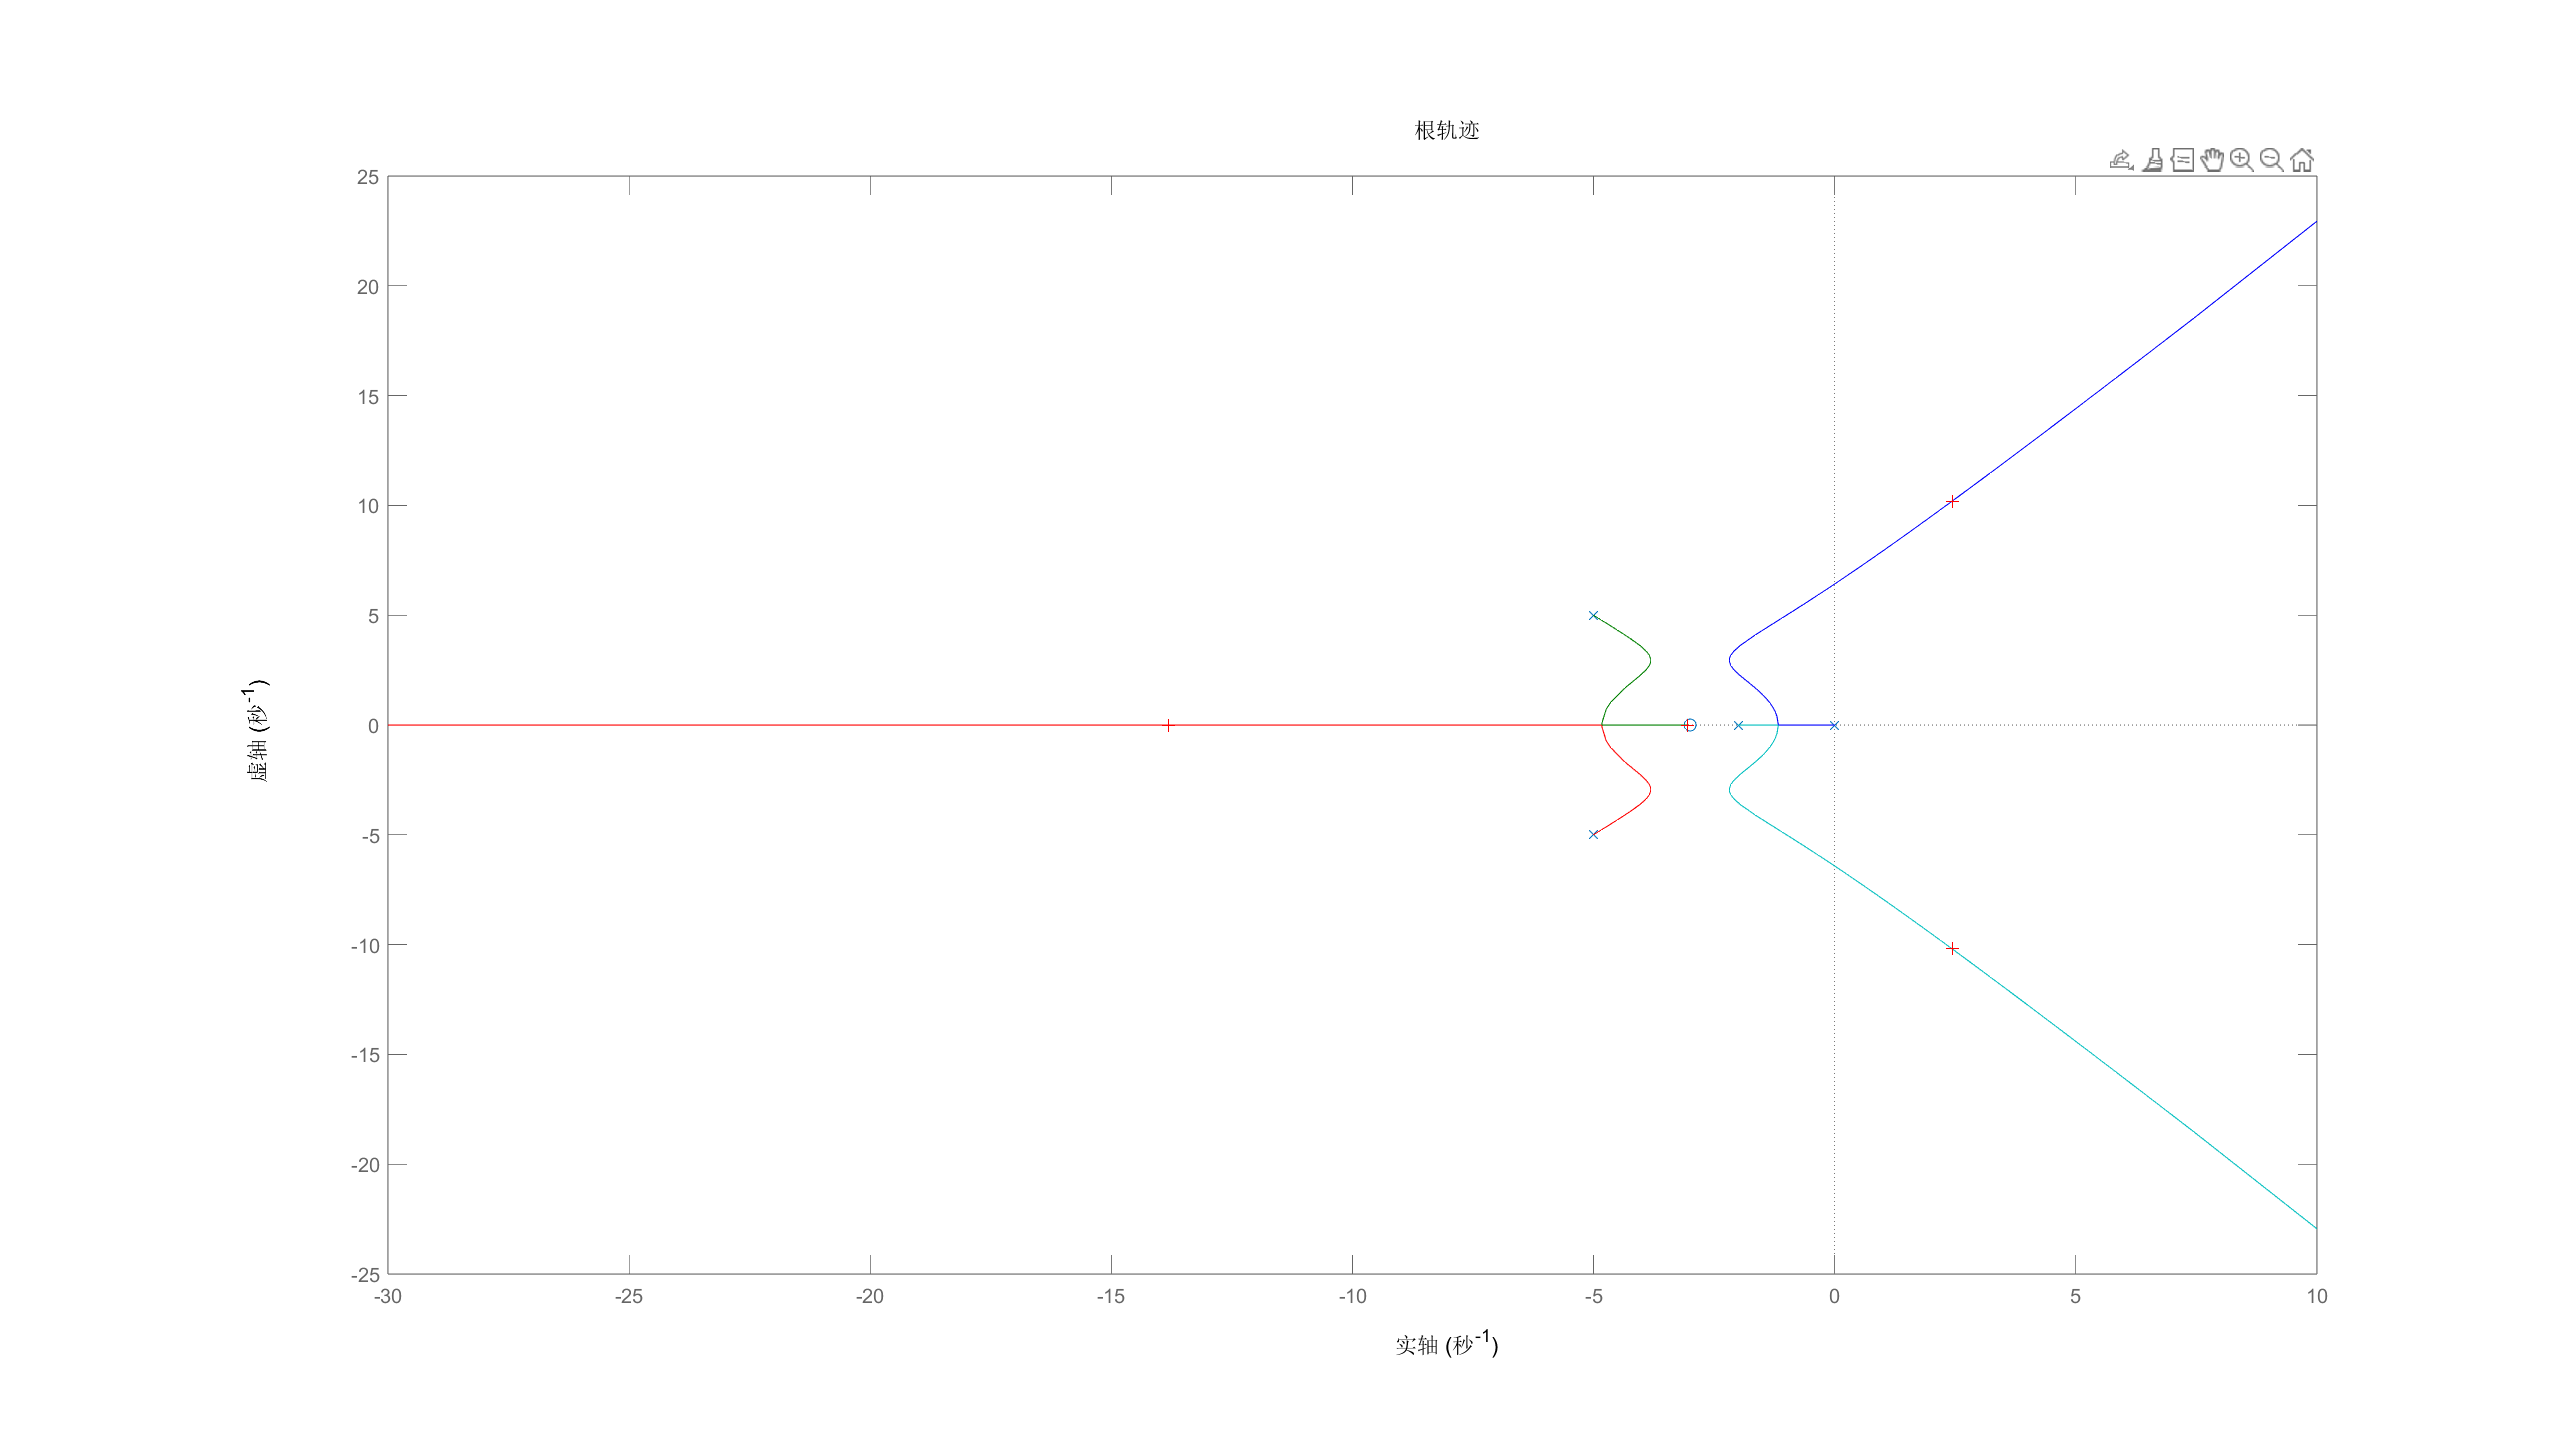

Select a point in the graphics window


selected_point = -11.6589 + 7.7641i

z=-3;
p=-10;
k=1;
[num,den]=zp2tf([],p,k);
rlocus(num,den);
rlocfind(num,den);

clf
num=1;
wn=10;
zeta=0.1:0.1:1.0;
hold on
for z=zeta
 den=[(1/wn)^2 2*z/wn 1];
 sys=tf(num,den);
 bode(sys)
end 
title('振荡环节频率特性')
hold off
